Completed 1 units of 149.
Completed 2 units of 149.
Completed 3 units of 149.
Completed 4 units of 149.
Completed 5 units of 149.
Completed 6 units of 149.
Completed 7 units of 149.
Completed 8 units of 149.
Completed 9 units of 149.
Completed 10 units of 149.
Completed 11 units of 149.
Completed 12 units of 149.
Completed 13 units of 149.
Completed 14 units of 149.
Completed 15 units of 149.
Completed 16 units of 149.
Completed 17 units of 149.
Completed 18 units of 149.
Completed 19 units of 149.
Completed 20 units of 149.
Completed 21 units of 149.
Completed 22 units of 149.
Completed 23 units of 149.
Completed 24 units of 149.
Completed 25 units of 149.
Completed 26 units of 149.
Completed 27 units of 149.
Completed 28 units of 149.
Completed 29 units of 149.
Completed 30 units of 149.
Completed 31 units of 149.
Completed 32 units of 149.
Completed 33 units of 149.
Completed 34 units of 149.
Completed 35 units of 149.
Completed 36 units of 149.
Completed 37 units of 149.
Completed 

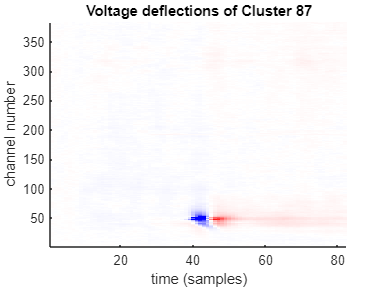

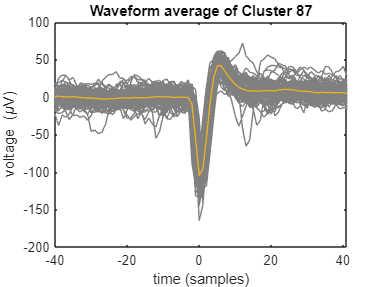

wf = struct with fields:
           unitIDs: [149×1 int32]
    spikeTimeKeeps: [149×100 double]
         waveForms: [149×100×383×82 double]
     waveFormsMean: [149×383×82 double]


clear all
Directory = "D:\Neuropixel_SSD\Jon_BlenderClips-01_V1_PFC-12_g0\Jon_BlenderClips-01_V1_PFC-12_g0_imec0";
spikes = readNPY(fullfile(Directory,"Clean_Spikes/Clean_spike_times.npy"));
clusters = readNPY(fullfile(Directory,"Clean_Spikes/Clean_spike_clusters.npy"));
window = [-40,41];
number_of_waveforms = 100;
sampling_frequency = 30000;
wf = clean_waveforms(Directory, spikes, clusters, window, number_of_waveforms,sampling_frequency)

cluOfInt = 11;
binSize = 0.001;
CCG_duration = 2;
[a,y] = CCG(spikes(clusters == wf.unitIDs(cluOfInt)),ones(length(clusters(clusters == wf.unitIDs(cluOfInt))),1),'binsize',binSize,'duration',CCG_duration);

cluster11 = 1.0e+03 *

    0.0064
    0.0068
    0.0078
    0.0084
    0.0091
    0.0092
    0.0117
    0.0165
    0.0167
    0.0167


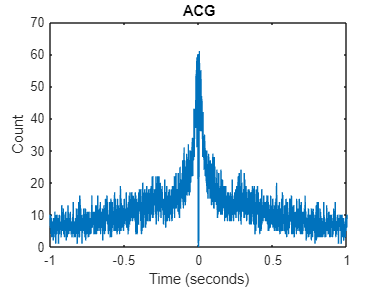


figure
plot(y,a), title('ACG'), xlabel('Time (seconds)'), ylabel('Count')